% ESPRIT DOA 估计性能三维图（引入蒙特卡洛机制）
clear; close all;

% 参数设置
wavelength = 1;
d = wavelength / 2;
design_ula = design_array_1d('ula', 12, d);
doas = [0, 0.5]; % 两个信号源，DOA = 0 和 0.5 弧度
source_count = length(doas);
% 计算 ESPRIT 参数 k
k = 2 * pi * d / wavelength; % k = 2*pi*d/wavelength = pi

% SNR 和快拍数范围
snr_db = -25:1:-10; % 步长 0.5 dB（41 个点）
snapshot_counts = 1:100:4000; % 步长 25（39 个点）
power_noise = 1;

% 蒙特卡洛仿真次数
monte_carlo_trials = 100;

% 初始化准确度矩阵
accuracy = zeros(length(snr_db), length(snapshot_counts));
failure_log = {}; % 记录失败点
tic;
% 计算每个 SNR 和快拍数的准确度得分（蒙特卡洛平均）
for i = 1:length(snr_db) % 使用 parfor 加速（可改为 for）
    power_source = power_noise * 10^(snr_db(i)/10);
    for j = 1:length(snapshot_counts)
        rmse_trials = zeros(1, monte_carlo_trials); % 存储每次仿真的 RMSE
        for trial = 1:monte_carlo_trials
            try
                % 生成协方差矩阵
                [~, R] = snapshot_gen_sto(design_ula, doas, wavelength, snapshot_counts(j), power_noise, power_source);
                % 确保 R 是正定的
                R = (R + R')/2; % 对称化
                R = R + 1e-6 * eye(size(R)); % 正则化
                if ~all(eig(R) > 0)
                    warning('SNR = %d dB, Snapshots = %d, Trial = %d: Covariance matrix not positive definite.', ...
                        snr_db(i), snapshot_counts(j), trial);
                    rmse_trials(trial) = NaN;
                    failure_log{end+1} = sprintf('SNR = %d dB, Snapshots = %d, Trial = %d: Non-positive definite R', ...
                        snr_db(i), snapshot_counts(j), trial);
                    continue;
                end
                % ESPRIT 估计
                sp = esprit_1d(R, source_count, k, 'Unit', 'radian');
                % 计算 RMSE
                est_doas = sp.x_est;
                % 确保 est_doas 有效
                if isempty(est_doas) || length(est_doas) ~= source_count || any(isnan(est_doas)) || any(isinf(est_doas))
                    warning('SNR = %d dB, Snapshots = %d, Trial = %d: Invalid est_doas (length: %d, values: [%s]).', ...
                        snr_db(i), snapshot_counts(j), trial, length(est_doas), num2str(est_doas));
                    rmse_trials(trial) = NaN;
                    failure_log{end+1} = sprintf('SNR = %d dB, Snapshots = %d, Trial = %d: Invalid est_doas (length: %d)', ...
                        snr_db(i), snapshot_counts(j), trial, length(est_doas));
                    continue;
                end
                % 匹配真实和估计 DOA
                [~, idx] = min(pdist2(est_doas(:), doas(:)), [], 2);
                sorted_est_doas = est_doas(idx);
                rmse_trials(trial) = sqrt(mean((sorted_est_doas - doas(:)).^2));
            catch err
                warning('SNR = %d dB, Snapshots = %d, Trial = %d: Error in ESPRIT: %s', ...
                    snr_db(i), snapshot_counts(j), trial, err.message);
                rmse_trials(trial) = NaN;
                failure_log{end+1} = sprintf('SNR = %d dB, Snapshots = %d, Trial = %d: %s', ...
                    snr_db(i), snapshot_counts(j), trial, err.message);
            end
        end
        % 计算平均 RMSE（忽略 NaN）
        mean_rmse = mean(rmse_trials, 'omitnan');
        if isnan(mean_rmse)
            accuracy(i, j) = NaN; % 如果所有仿真失败，设为 NaN
        else
            % 新评价标准：e^(-mean_rmse)
            accuracy(i, j) = exp(-mean_rmse);
        end
    end
end
toc;

历时 25.793150 秒。


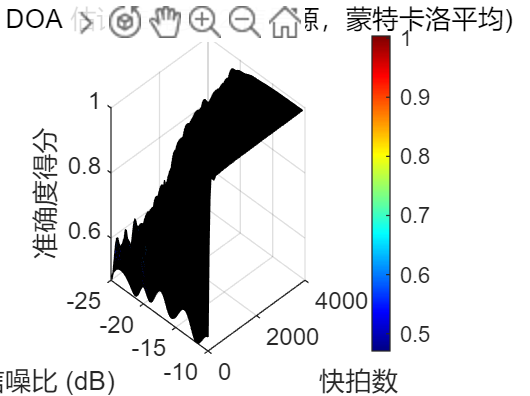

% 处理 NaN 值以确保绘图
if all(isnan(accuracy(:)))
    warning('All accuracy values are NaN. Using default accuracy = 0 for plotting.');
    accuracy(isnan(accuracy)) = 0; % 如果全 NaN，用 0
else
    min_accuracy = min(accuracy(~isnan(accuracy)), [], 'all');
    if isempty(min_accuracy)
        min_accuracy = 0; % 防止 min_accuracy 为空
    end
    accuracy(isnan(accuracy)) = min_accuracy; % 用最小非 NaN 准确度替换
end

% 插值以平滑图像
[X, Z] = meshgrid(snr_db, snapshot_counts);
[Xq, Zq] = meshgrid(linspace(min(snr_db), max(snr_db), 100), linspace(min(snapshot_counts), max(snapshot_counts), 100));
accuracy_interp = interp2(X, Z, accuracy', Xq, Zq, 'spline'); % 使用样条插值

% 绘制三维图
figure;
surf(Xq, Zq, accuracy_interp);
xlabel('信噪比 (dB)');
ylabel('快拍数');
zlabel('准确度得分');
title('ESPRIT DOA 估计准确度 (2 信号源，蒙特卡洛平均)');
colormap('jet');
colorbar;
grid on;
view(45, 30);


% 显示失败日志
if ~isempty(failure_log)
    fprintf('失败点日志：\n');
    for k = 1:length(failure_log)
        fprintf('%s\n', failure_log{k});
    end
end

% 可选：保存图像
saveas(gcf, 'ESPRIT-3D.fig');